# Bézier curve

Design a Bezier curve controlled by four  points:  


$$P_0 =\left(1,1\right);{\;P}_1 =\left(2,3\right);{\;P}_{2\;} =\left(4,3\right);\;P_3 =\left(6,4\right)$$
 

There  are 4 given control points, therefore degree $n=3\;$(number of control points - 1) 

Equation of Bezier curve is given by 


$$$P(u) = \sum_{i=0}^{n} P_i B_{i,n}(u) $
$$


where 


$$B_{i,n}(u) = \frac{n!}{i!(n-1)!}u^i (1-u)^{n-i}$$


For $n=3,$ we have 


$$P(u) = P_0 B_{0,3}(u)  + P_1 B_{1,3}(u) + P_2 B_{2,3}(u) +  P_3B_{3,3}(u)$$


We can calculate 


$$B_{0,3}(u) = \frac{3!}{0!3!} (1-u)^3 = (1-u)^3 \\ 
B_{1,3}(u) =  3u(1-u)^2 \\ 
B_{2,3}(u) = 3u^2(1-u) \\
B_{3,3}(u) = u^3$$


Therefore,


$$P_x(u) = x_0 (1-u)^3 + x_1 3u(1-u)^2  + x_2 3u^2(1-u) +  x_3 u^3\\ 
P_y(u) = y_0 (1-u)^3   + y_1 3u(1-u)^2  + y_2 3u^2(1-u) +  y_3 u^3
$$


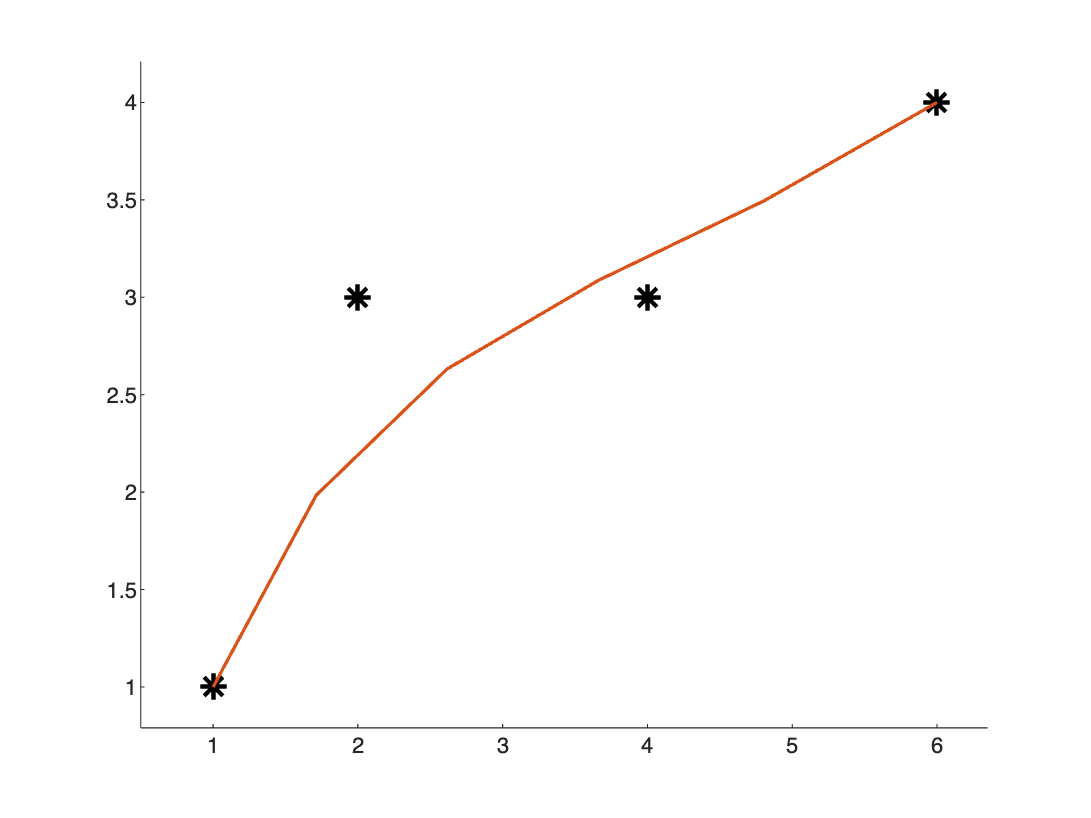

P0 = [1,1]; 
P1 = [2,3]; 
P2 = [4,3]; 
P3 = [6,4]; 

xbezier = @(u,x0,x1,x2,x3) x0*(1-u).^3 + x1*(3*u.*(1-u).^2) + x2*(3*u.^2).*(1-u) + x3*u.^3;
ybezier = @(u,y0,y1,y2,y3) y0*(1-u).^3 + y1*(3*u.*(1-u).^2) + y2*(3*u.^2).*(1-u) + y3*u.^3;

P = [P0;P1;P2;P3]; 
u = 0:0.2:1; 
figure; hold on; axis('padded')
plot(P(:,1),P(:,2),'k*',MarkerSize=12,LineWidth=2)
plot(xbezier(u,P0(1),P1(1),P2(1),P3(1)), ...
    ybezier(u,P0(2),P1(2),P2(2),P3(2)), LineWidth=1.5)